# Exercise 2

## 2a

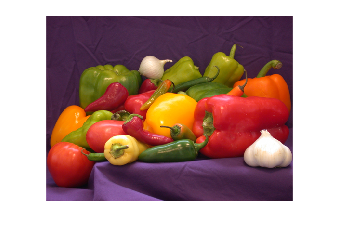

figure
I = imread('peppers.png');
imshow(I);

## 2b

## Blur Gaussian filter

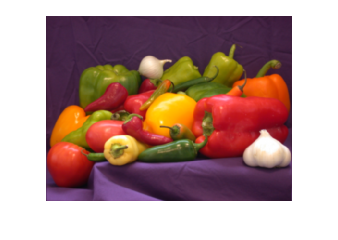

h = 1/256*[1 4 6 4 1; 4 16 24 16 4; 6 24 36 24 6; 4 16 24 16 4; 1 4 6 4 1];
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

## Motion filter

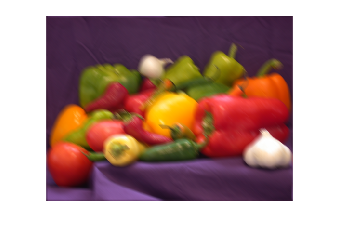

h = zeros(9, 9);
for i = 1:length(h)
    h(i, i) = 1;
end
h = h/sum(sum(h));
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

## Sharpening

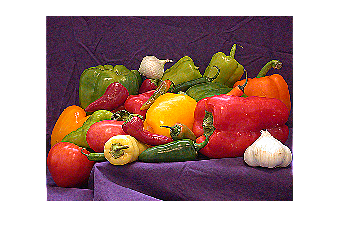

h = [-1 -1 -1; -1 9 -1; -1 -1 -1];
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

## Edge detection

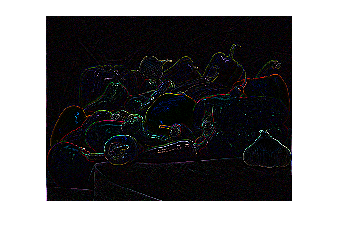

h = [-1 -1 -1; -1 8 -1; -1 -1 -1]; 
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

## Horizontal line detection

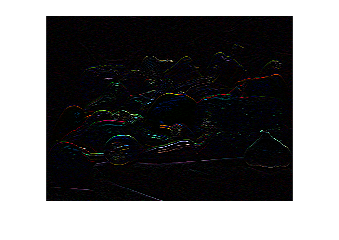

h = [-1 -1 -1; 2 2 2; -1 -1 -1]; 
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

## Vertical line detection

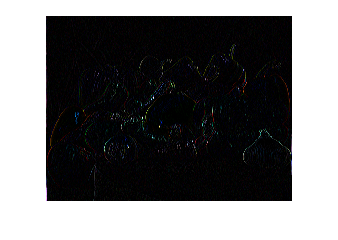

h = [-1 2 -1; -1 2 -1; -1 2 -1]; 
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

## 2c

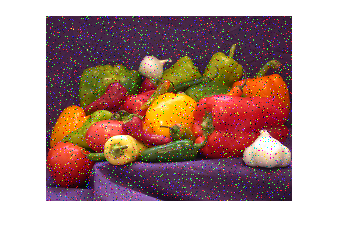

If2 = imnoise(I, 'salt & pepper');
imshow(If2);

## 2d

imwrite(If, 'photo1_noise', 'jpg');

## 2e

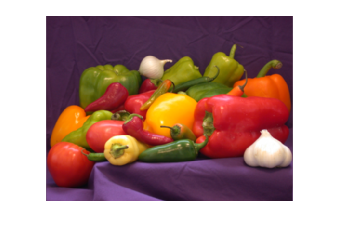

h = 1/9*[1 1 1; 1 1 1; 1 1 1];
If = imfilter(I, h, 'conv', 'circular');
imshow(If);

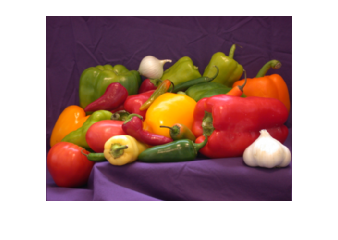


% The image becomes brighter if we increase the filter size
h = 1/9*[1 1 1; 1 1 1; 1 1 1];
If = imfilter(I, h, 'conv', 'circular');
imshow(If);